[https://blog.csdn.net/xfijun/article/details/105670892](https://blog.csdn.net/xfijun/article/details/105670892)

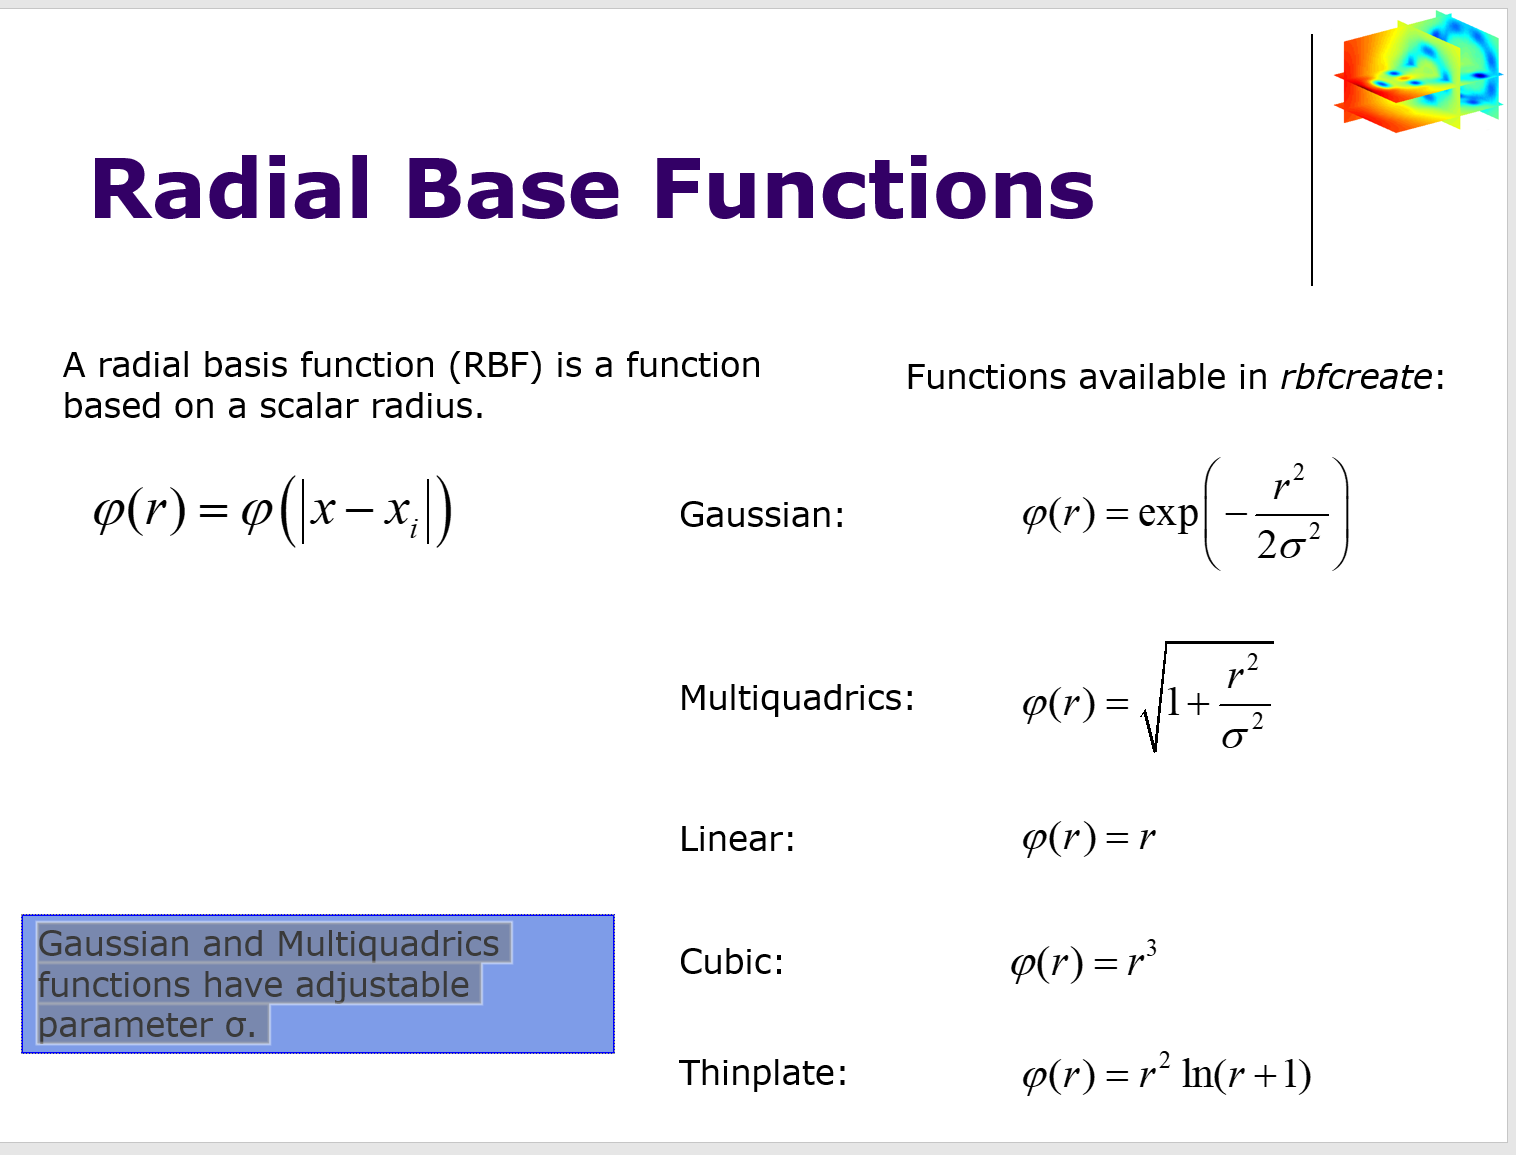

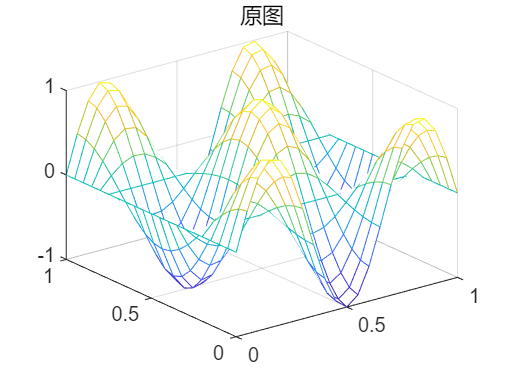

clc,clear,close all

f = @(x,y) sin(3*pi*x).*cos(2*pi*y);


sigma = 0.4;
n = 50;
hh = 0.05;
varphi = @(r) exp(-r.^2/(2*sigma^2));
x1 = 0;    % x的下限
x2 = 1;    % x的上限
y1 = 0;    % y的下限
y2 = 1;    % y的上限
x = unifrnd(x1,x2,[n,1]);   % 已知点的x坐标
y = unifrnd(y1,y2,[n,1]);   % 已知点的y坐标
z = f(x,y);

[xx,yy] = meshgrid(x1:hh:x2,y1:hh:y2); % 待求点的y坐标
zz = zeros(size(xx));
b = z;
A = zeros(length(x));
for i = 1:length(x)
    for j = 1:length(x)
        r = norm([x(i) y(i)] - [x(j) y(j)]);
        A(i,j) = varphi(r);
    end
end
w = A\b;
for i = 1:length(xx)
    for j = 1:length(xx)
        r = zeros(n,1);
        for k = 1:n
            r(k) = norm([xx(i,j) yy(i,j)] - [x(k) y(k)]);
        end
        zz(i,j) = sum(w.*varphi(r));
    end
end
mesh(xx,yy,f(xx,yy))
title('原图')

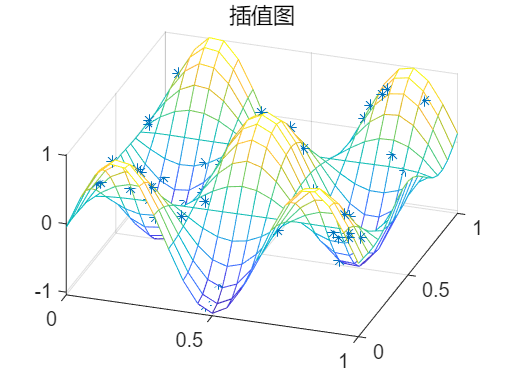

mesh(xx,yy,zz)
title('插值图')
hold on
plot3(x,y,z,'*')

max(max(abs(zz-f(xx,yy))))

ans = 0.3326